# Compare TNG quenched fraction with Romulus  & Wetzel 2012 

## Read TNG data

load('/home/zinger/workProjects/matlab_scripts/IllustrisTNG/matFiles/quenchedFractions_z0.mat')

## Read Romulus and Wetzel 2012 data 

RomC_data;
load('/home/zinger/workProjects/matlab_scripts/rpsProject/matFiles/wetzel.mat')


## Compare to Tremmel 2018 Figure 14 : QF as a function of stellar mass 


% prepare Tremmel
dbT=diff(fig14.massBinC); % horizon. error bar
mbT=fig14.massBinC(1:end-1)+0.5.*dbT;

% prepare TNG 100 quenched fractions
db=diff(smBin);
smb=smBin(1:end-1)+db/2;

nbin100=squeeze(sum(nbinT100(:,:,1:4),3)); %sum over all positions
qbin100=squeeze(sum(qbinT100(:,:,1:4),3));  % sum over all positions
qf100=qbin100./nbin100;
qf100(nbin100==0)=0;

err100=qf100.*sqrt( (qbin100.^3+nbin100.^3)./(qbin100.^3.*nbin100.^3));
err100(nbin100==0)=0;

nbin300=squeeze(sum(nbinT300(:,:,1:4),3)); %sum over all positions
qbin300=squeeze(sum(qbinT300(:,:,1:4),3));  % sum over all positions
qf300=qbin300./nbin300;
qf300(nbin300==0)=0;

err300=qf300.*sqrt( (qbin300.^3+nbin300.^3)./(qbin300.^3.*nbin300.^3));
err300(nbin300==0)=0;


cmap=brewermap(8,'Set1');
%figure('position',[ 1756 452 805 724])
figure
h=[];
cnt=0

cnt = 0

for j=3 %1:length(hmBin)-1
    %j=3;
    cnt=cnt+1;
    str1=sprintf('$100:[10^{%s}\\,-\\,10^{%s}]$',num2str(hmBin(j)),num2str(hmBin(j+1)));
    str3=sprintf('$300:[10^{%s}\\,-\\,10^{%s}]$',num2str(hmBin(j)),num2str(hmBin(j+1)));
    %errorbar(smb,qbin(:,j),db/2,'o')
    
    h(1)=errorbar(smb,qf100(:,j),err100(:,j),err100(:,j),'x',...
        'color',cmap(1,:),'DisplayName',str1);
    %db/2,db/2
    hold on
    h(2)=errorbar(smb,qf300(:,j),err300(:,j),err300(:,j),'x',...
        'color',cmap(2,:),'DisplayName',str3);
    %db/2,db/2
end
h(3)=errorbar(mbT,fig14.qfC,fig14.errM_C,fig14.errP_C,'.',...
    'color',cmap(3,:),...
    'DisplayName','RomulusC');
%dbT/2,dbT/2,'.',...
h(4)=plot(Wetzel12_fig14(2,:),Wetzel12_fig14(1,:),'dk','markerfacecolor','k',...
    'DisplayName','Wetzel+12');


hl=legend(h);
set(hl,'Interpreter','latex','location','NorthEastOutside','fontsize',10)
grid
xlim([8 12])
ylim([0.4 1])

xlabelmine('log Stellar Mass')

ans =   Text (log Stellar Mass) with properties:

                 String: 'log Stellar Mass'
               FontSize: 14
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [10.0000 0.3586 -1.0000]
                  Units: 'data'

  Show all properties


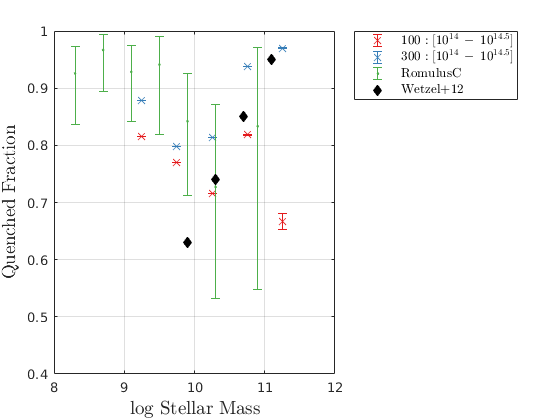

ans =   Text (Quenched Fraction) with properties:

                 String: 'Quenched Fraction'
               FontSize: 14
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [7.5502 0.7000 -1.0000]
                  Units: 'data'

  Show all properties


ylabelmine('Quenched Fraction')

%titlemine('By steller mass')


%printout_fig(gcf,['quenchedFraction_stellarMass_' simDisplayName],'v')


## Compare to Fig 15 from Tremmel 2018

% prepare Tremmel
%dbT=diff(fig14.massBinC); % horizon. error bar
%mbT=fig14.massBinC(1:end-1)+0.5.*dbT;

% prepare TNG 100 quenched fractions
%db=diff(smBin);
%smb=smBin(1:end-1)+db/2;
rb=[0 rbin(1:8)];
rb=rb(1:end-1)+diff(rb)/2;

 j=3;  % set right host mass range

% do low mass <10^10

nb=squeeze(nbinT100(:,j,1:8));
nbin100=squeeze(sum(nb(1:3,:),1));

qb=squeeze(qbinT100(:,j,1:8));
qbin100=squeeze(sum(qb(1:3,:),1));
qf100=qbin100./nbin100;
qf100(nbin100==0)=0;

err100=qf100.*sqrt( (qbin100.^3+nbin100.^3)./(qbin100.^3.*nbin100.^3));
err100(nbin100==0)=0;

nb=squeeze(nbinT300(:,j,1:8));
nbin300=squeeze(sum(nb(1:3,:),1));

qb=squeeze(qbinT300(:,j,1:8));
qbin300=squeeze(sum(qb(1:3,:),1));
qf300=qbin300./nbin300;
qf300(nbin300==0)=0;

err300=qf300.*sqrt( (qbin300.^3+nbin300.^3)./(qbin300.^3.*nbin300.^3));
err300(nbin300==0)=0;

qf100Low=qf100;
qf300Low=qf300;
err100Low=err100;
err300Low=err300;

% do high mass >10^10
nb=squeeze(nbinT100(:,j,1:8));
nbin100=squeeze(sum(nb(4:end,:),1));

qb=squeeze(qbinT100(:,j,1:8));
qbin100=squeeze(sum(qb(4:end,:),1));
qf100=qbin100./nbin100;
qf100(nbin100==0)=0;

err100=qf100.*sqrt( (qbin100.^3+nbin100.^3)./(qbin100.^3.*nbin100.^3));
err100(nbin100==0)=0;

nb=squeeze(nbinT300(:,j,1:8));
nbin300=squeeze(sum(nb(4:end,:),1));

qb=squeeze(qbinT300(:,j,1:8));
qbin300=squeeze(sum(qb(4:end,:),1));
qf300=qbin300./nbin300;
qf300(nbin300==0)=0;

err300=qf300.*sqrt( (qbin300.^3+nbin300.^3)./(qbin300.^3.*nbin300.^3));
err300(nbin300==0)=0;

qf100Hi=qf100;
qf300Hi=qf300;
err100Hi=err100;
err300Hi=err300;


cmap=brewermap(8,'Set1');
%figure('position',[ 1756 452 805 724])
figure
h=[];


%j=3;

str1Low='$100,<10^{10}$';
str1Hi='$100,>10^{10}$';
str3Low='$300,<10^{10}$';
str3Hi='$300,>10^{10}$';
%errorbar(smb,qbin(:,j),db/2,'o')

rdistBLow=fig15.rdistLow(1:end-1)+0.5.*diff(fig15.rdistLow);



## plot Hi

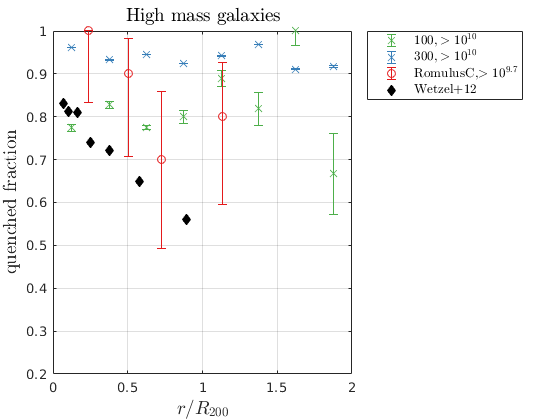


% h(end+1)=errorbar(rb,qf100Low,err100Low,err100Low,'x',...
%     'color',cmap(3,:),'DisplayName',str1Low);
%db/2,db/2


h=[];
figure
h(end+1)=errorbar(rb,qf100Hi,err100Hi,err100Hi,'x',...
    'color',cmap(3,:),'DisplayName',str1Hi);
hold on 

h(end+1)=errorbar(rb,qf300Hi,err300Hi,err300Hi,'x',...
    'color',cmap(2,:),'DisplayName',str3Hi);

%db/2,db/2

% h(end+1)=errorbar(rb,qf300Hi,err300Hi,err300Hi,'x',...
%     'color',cmap(2,:),'DisplayName',str3Hi);
%     'color',cmap(2,:),...
%     'DisplayName','RomulusC,$>0^{9.7}$');
hold on 

h(end+1)=errorbar(fig15.rdist,fig15.qf,fig15.errM,fig15.errP,'o',...
    'color',cmap(1,:),...
    'DisplayName','RomulusC,$>10^{9.7}$');

h(end+1)=plot(Wetzel12_fig15(2,:),Wetzel12_fig15(1,:),'dk','markerfacecolor','k',...
    'DisplayName','Wetzel+12');


% h(end+1)=errorbar(fig15.rdist,fig15.qf,fig15.errM,fig15.errP,'o',...


%dbT/2,dbT/2,'.',...
%h(4)=plot(Wetzel12_fig14(2,:),Wetzel12_fig14(1,:),'dk','markerfacecolor','k',...
%    'DisplayName','Wetzel+12');


hl=legend(h);
set(hl,'Interpreter','latex','location','NorthEastOutside','fontsize',10)
grid
xlim([0 2])
ylim([0.2 1])

xlabelmine('$r/R_{200}$');

ylabelmine('quenched fraction');

titlemine('High mass galaxies');

## plot Low

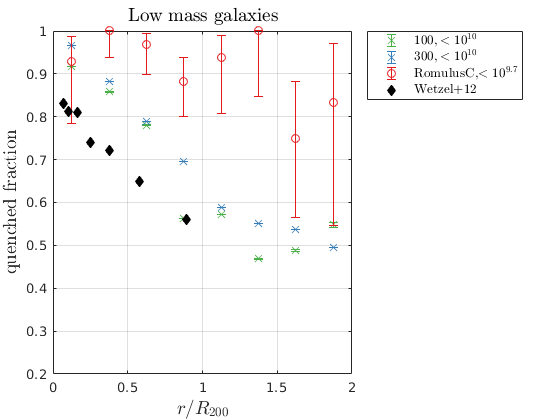

h=[];
figure

h(end+1)=errorbar(rb,qf100Low,err100Low,err100Low,'x',...
    'color',cmap(3,:),'DisplayName',str1Low);
%db/2,db/2
hold on
% h(end+1)=errorbar(rb,qf100Hi,err100Hi,err100Hi,'x',...
%     'color',cmap(3,:),'DisplayName',str1Hi);


h(end+1)=errorbar(rb,qf300Low,err300Low,err300Low,'x',...
    'color',cmap(2,:),'DisplayName',str3Low);
hold on 
%db/2,db/2

% h(end+1)=errorbar(rb,qf300Hi,err300Hi,err300Hi,'x',...
%     'color',cmap(4,:),'DisplayName',str3Hi);



h(end+1)=errorbar(rdistBLow,fig15.qfLow,fig15.errMlow,fig15.errPlow,'o',...
    'color',cmap(1,:),...
    'DisplayName','RomulusC,$<10^{9.7}$');

h(end+1)=plot(Wetzel12_fig15(2,:),Wetzel12_fig15(1,:),'dk','markerfacecolor','k',...
    'DisplayName','Wetzel+12');



%dbT/2,dbT/2,'.',...
%h(4)=plot(Wetzel12_fig14(2,:),Wetzel12_fig14(1,:),'dk','markerfacecolor','k',...
%    'DisplayName','Wetzel+12');


hl=legend(h);
set(hl,'Interpreter','latex','location','NorthEastOutside','fontsize',10)
grid
xlim([0 2])
ylim([0.2 1])

xlabelmine('$r/R_{200}$');
ylabelmine('quenched fraction');
titlemine('Low mass galaxies');